t_pri = 0.1;
fs = 5000;
len = 20;
bits = randi([0 1], 1, len)

bits =      1     1     0     1     1     0     0     1     1     1     0     1     1     0     1     0     0     1     1     1


encd_msg = fm0(bits, t_pri, fs);

L = len*t_pri*fs;
n = 2^nextpow2(L)

n = 16384

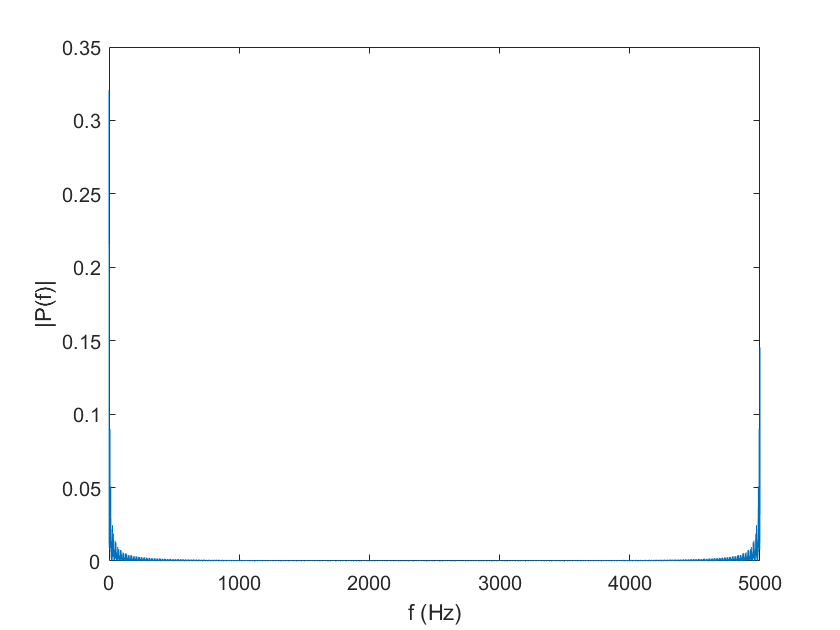

Y = fft(encd_msg, n);
f = (1:n)*fs/n;
P1 = abs(Y/n);
plot(f, P1)
xlabel('f (Hz)')
ylabel('|P(f)|')

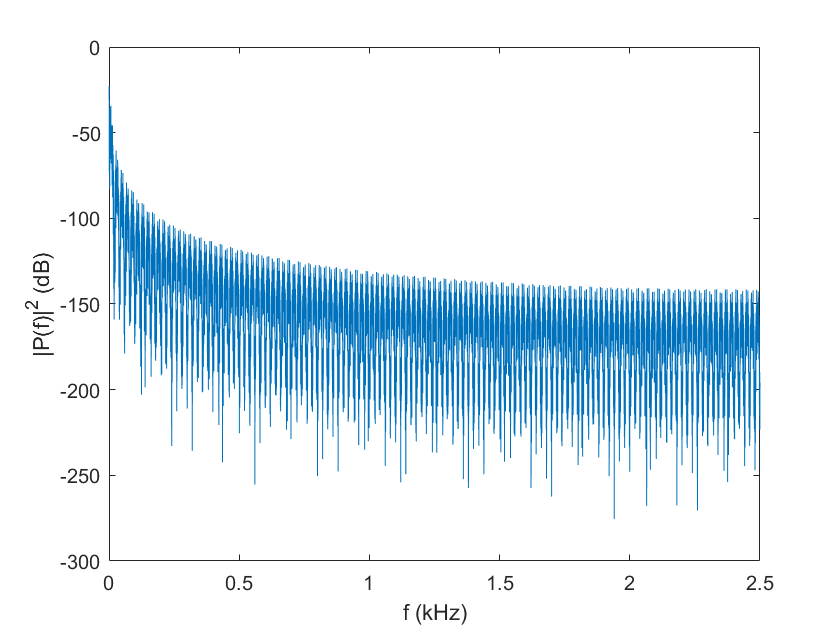

P2 = P1(1:n/2+1);
P2(2:end) = 2*P2(2:end);
P2 = P2.^2;
plot(f(1:n/2+1)/1000, 10*log10(P2(1:n/2+1)))
xlabel('f (kHz)')
ylabel('|P(f)|^2 (dB)')

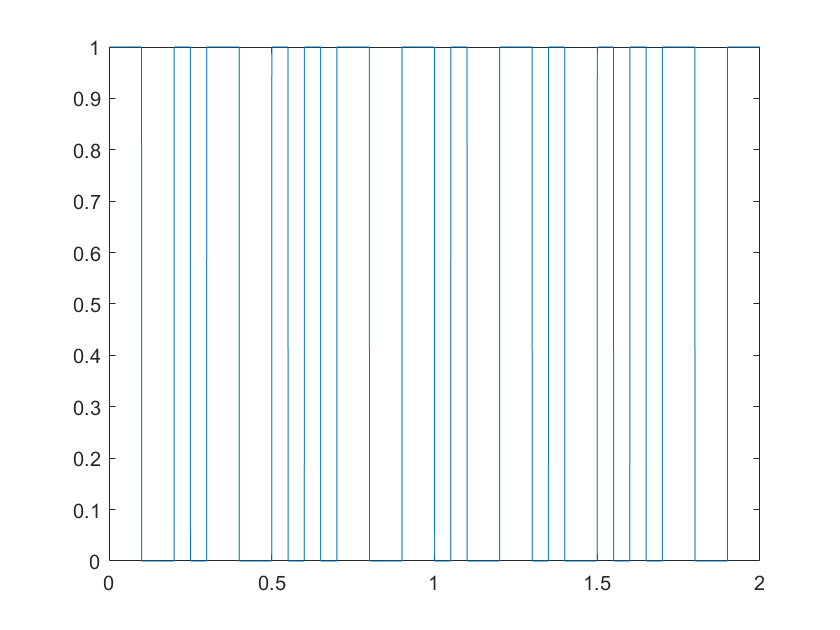

t = 1/fs : 1/fs : len * t_pri;
plot(t, encd_msg)

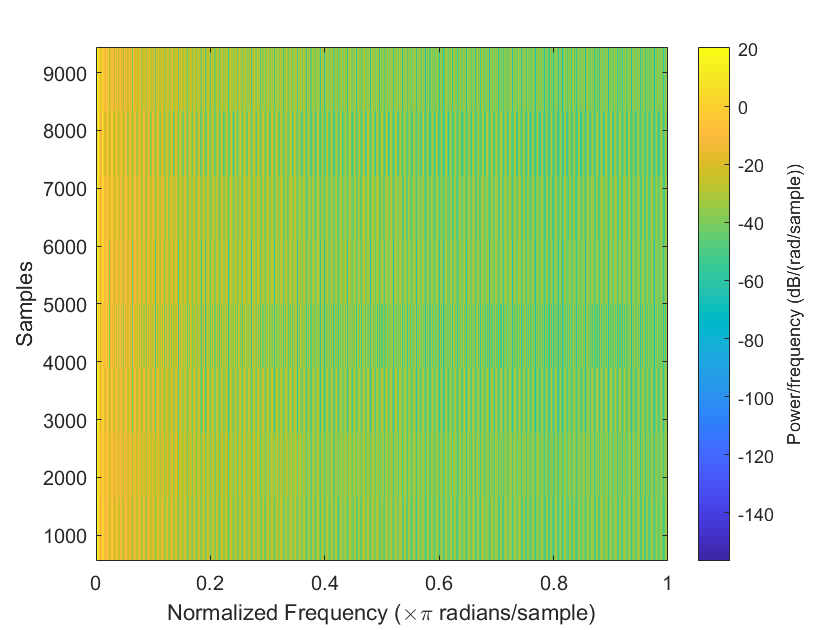

spectrogram(encd_msg)

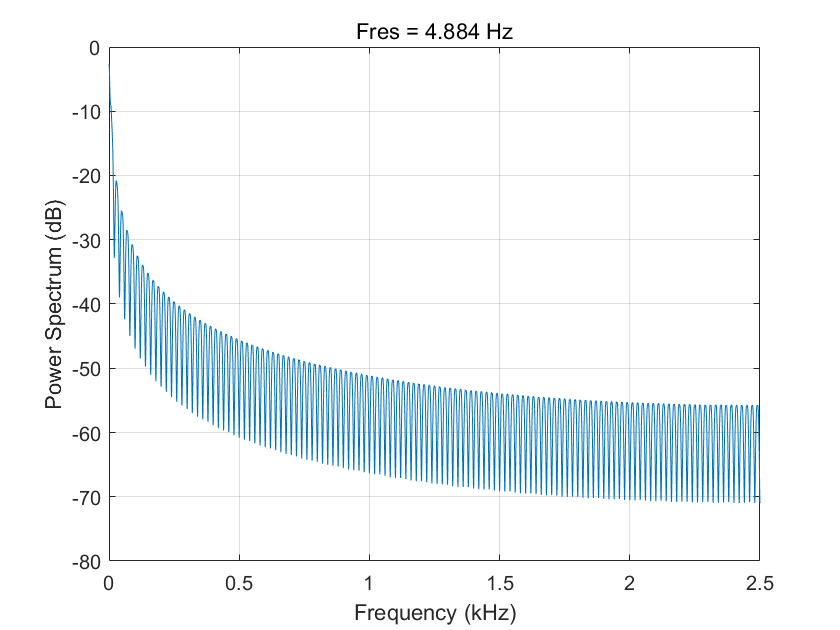

pspectrum(encd_msg, fs)